# **MATLAB graphics**

## **Plotting**

When working with data it is often useful to visualise so that it can be understood more easily. MATLAB has extensive data visualisation abilities built in. The simplest possible plot is a 2-dimensional graph. This example will plot the value of the sine function against the input angle: 

angles = -180:1:180 % generate a vector of angles

angles =   -180  -179  -178  -177  -176  -175  -174  -173  -172  -171  -170  -169  -168  -167  -166  -165  -164  -163  -162  -161  -160  -159  -158  -157  -156  -155  -154  -153  -152  -151  -150  -149  -148  -147  -146  -145  -144  -143  -142  -141  -140  -139  -138  -137  -136  -135  -134  -133  -132  -131


sine_x = sind(angles)

sine_x =          0   -0.0175   -0.0349   -0.0523   -0.0698   -0.0872   -0.1045   -0.1219   -0.1392   -0.1564   -0.1736   -0.1908   -0.2079   -0.2250   -0.2419   -0.2588   -0.2756   -0.2924   -0.3090   -0.3256   -0.3420   -0.3584   -0.3746   -0.3907   -0.4067   -0.4226   -0.4384   -0.4540   -0.4695   -0.4848   -0.5000   -0.5150   -0.5299   -0.5446   -0.5592   -0.5736   -0.5878   -0.6018   -0.6157   -0.6293   -0.6428   -0.6561   -0.6691   -0.6820   -0.6947   -0.7071   -0.7193   -0.7314   -0.7431   -0.7547


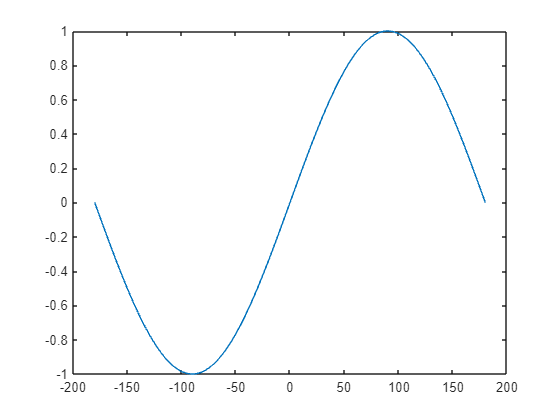


% the plot(x,y) function takes as input a vector of x and y data. 
% Note, both vector must have the same number of elements
plot(angles, sine_x)

The data is now plotted, but we are missing axis-labels, a title, and a legend. We can customise this figure:

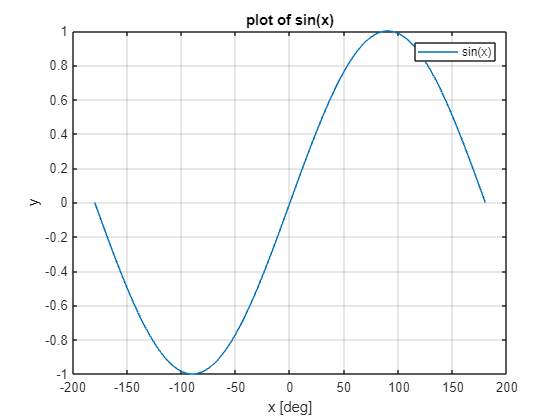

grid()                  % add a grid to the current figure
xlabel("x [deg]")       % add a label to x-axis
ylabel("y")             % add a label to y-axis
title("plot of sin(x)") % add a title
legend(["sin(x)"])      % a key (legend)

In the above example, the data points were connected with lines. This is not always desirable, and it may be preferable to plot the individual data points:

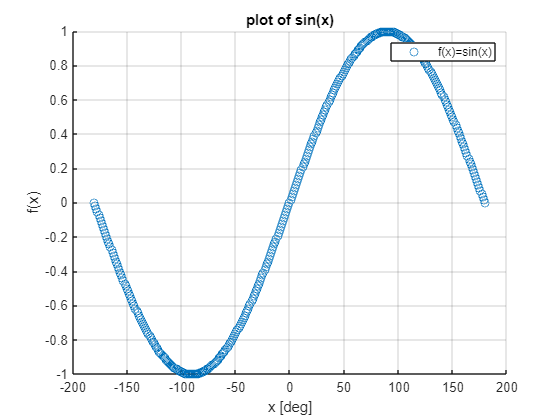

scatter(angles, sine_x) % plot the data points instead of connecting with a line

grid()                  % add a grid to the current figure
xlabel("x [deg]")       % add a label to x-axis
ylabel("f(x)")          % add a label to y-axis
title("plot of sin(x)") % add a title
legend(["f(x)=sin(x)"]) % a key (legend)

Often, it is desirable to plot multiple lines on the same graph. To do this, MATLAB has the command "hold on", which tells MATLAB to plot all further items onto the same graph:

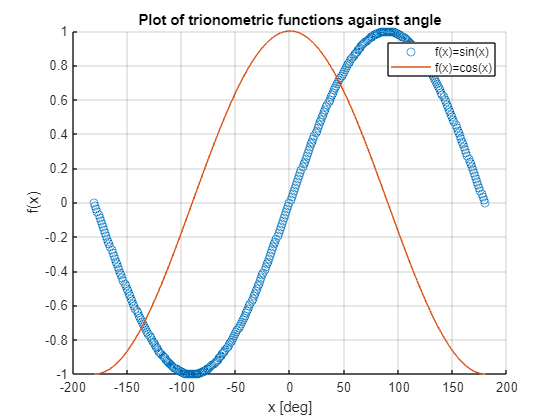

hold on % tells MATLAB to plot onto the same graph

cosine_x = cosd(angles);
plot(angles, cosine_x) % by default next plot has a different colour
legend(["f(x)=sin(x)", "f(x)=cos(x)"])
title("Plot of trionometric functions against angle")

MATLAB adjusts the limits (maximum shown value on a figure) dynamically to show all the current data being plotted. But it is possible to tell MATLAB what axis limits to use:

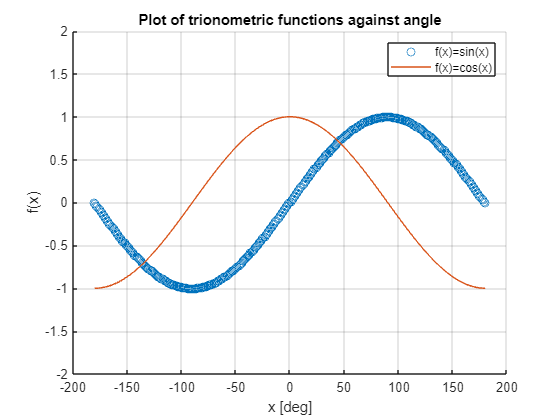

xlim([-200, 200])   % minimum and maximum 'x' value to show
ylim([-2, 2])       % minimum and maximum 'y' value to show

## Subplotting

Often, it is desirable to graph different quantities on the same figure next to each other. In this example, we plot the acceleration, velocity and position of an object falling in a vacuum. 

An object falling under the influence of gravity on earth accelerates at a constant rate of 9.81 m/s^2. If acceleration ($a
$) is constant with respect to time, then the velocity is linear ($v
$) and the position $p
$ quadratic with respect to time ($t$):


$$a = 9.81
\\
v = a\cdot t 
\\ 
p = \frac{1}{2}\cdot a \cdot t^2
$$


We will now use subplot to plot this data. The first step is to create the data:

t = 0:0.5:10;                 % time to plot

a = -9.81.*ones(size(t));     % acceleration is constant 
v = a.*t;                     % velocity at time t
p = 0.5*a.*t.^2;              % position at time t


The "subplot(*m*, *n*,* p*)" function can be used to create multiple plots side by side on the same figure. It takes as input argument the number of rows of sub figures (*m*), the number of columns of subfigures (*n*), and a third argument (*p*) this third argument tells MATLAB which of the figures to plot the next call to a graphing function. In this we want to plot acceleration, velocity and position, so we need 3 figures, which will be arranged into separate columns:

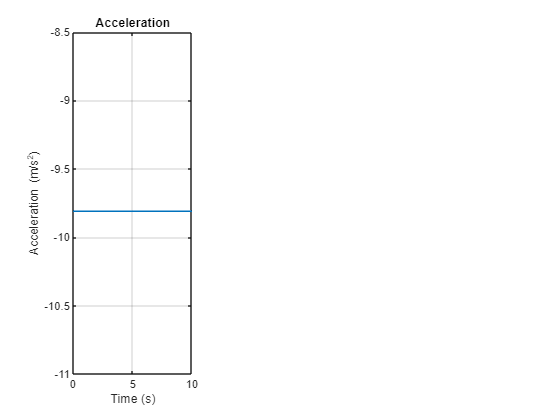

subplot(1, 3, 1) % 1 row, 3 columns and the active plot is 1
plot(t, a)
xlabel("Time (s)")
ylabel("Acceleration (m/s^2)")
title("Acceleration")
grid()

The first plot exists, to activate the second plot we make another call to the subplot function but this time specify that the active figure should be the second subfigure:

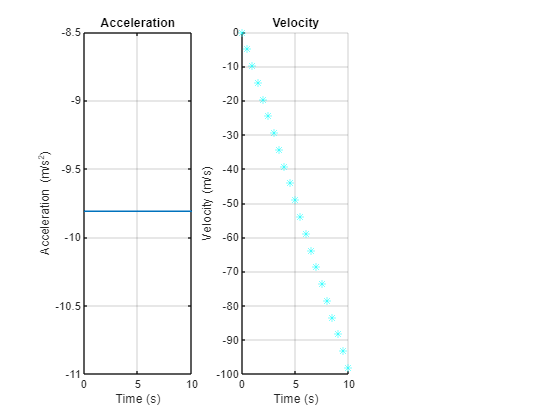

subplot(1, 3, 2) % switch active plot to 2
scatter(t, v, 'cyan *') % specify plot colour as cyan and data point style as *
xlabel("Time (s)")
ylabel("Velocity (m/s)")
title("Velocity")
grid()

To complete the graph, make a third call to the subplot function activating figure 3:

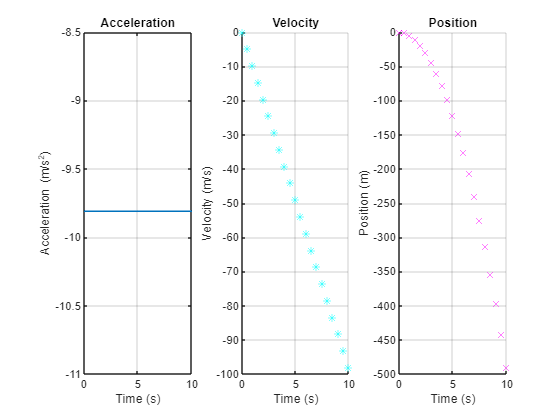

subplot(1, 3, 3) % switch active plot to 3
scatter(t, p, 'magenta x') % specify plot colour as magenta and data point style as x
xlabel("Time (s)")
ylabel("Position (m)")
title("Position")
grid()
hold off

## 3D plotting

So far we have seen how to create simple 2-dimensional plots. MATLAB has extensive functionality built-in to support plotting in 3D dimensions. Rather than creating figures via that code MATLAB also has the "PLOTS" toolbar at the top left which can be used to interactively create plots from existing variables in the workspace.

Two common plots are surface plots and contour plots. Not all the associated functions have been covered but extensive documentation and examples are available le via the MATLAB documentation. We will now use MATLAB to plot $z=sin(x)+ y^2$:

clf
x = -180:10:180

x =   -180  -170  -160  -150  -140  -130  -120  -110  -100   -90   -80   -70   -60   -50   -40   -30   -20   -10     0    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180


y = -1.8:0.1:1.8

y =    -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000



[X, Y] = meshgrid(x, y);
z = sind(X) + Y.^2;


3 Dimensional coloured surface plot:

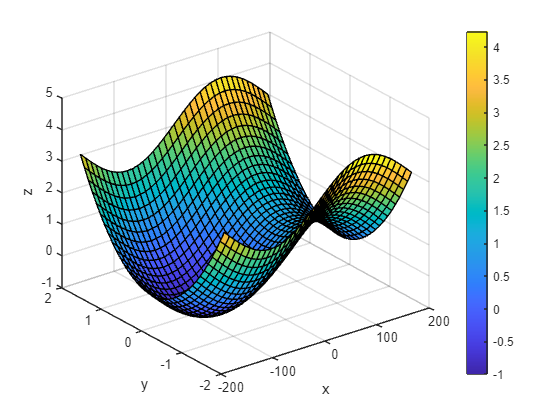

surf(X, Y, z)
xlabel("x")
ylabel("y")
zlabel("z")
colorbar      % add a colour bar

2 Dimensional contour plot:

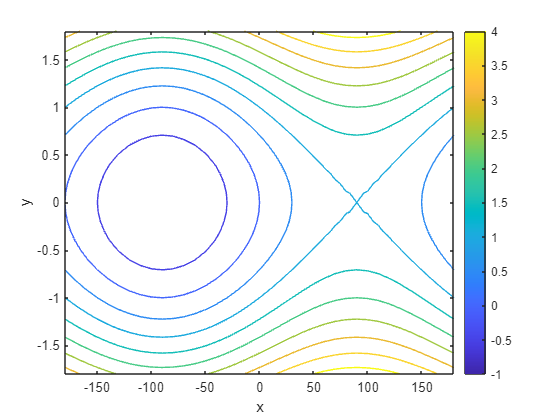

contour(X,Y,z)
xlabel("x")
ylabel("y")
colorbar      % add a colour bar

## Interactive plotting

The figure is plotted in the output box in MATLAB live scripts (such as here). Usually, the output figure is created in a separate window when working in standard MATLAB scripts. MATLAB allows editing and manipulation of the view via the figure GUI. This functionality is especially useful for 3-dimensional plots as the data can be investigated from different perspectives. You are encouraged to take the 3D plotting code above and put it into a standard MATLAB script and to investigate the figure GUI. Alternatively, you can select the figure in the output menu and press the arrow with the description: "Open in figure window" to open the figure in a separate window.